# IMPORTANT: BEFORE YOU START!

Do **NOT** click on the green run button!

Execute this script by stepping section to section, read instructions and inspect results.

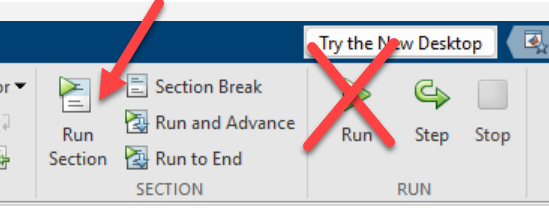

## Exercise 2: Simulate the RF receiver

Number of steps: 4 

Expected completion time: 20 minutes

In this section, the model of the RF receiver is integrated into the system-level testbench.

**2.1 **From the RF Budget Analyzer app **generate an RF Blockset Circuit Envelope** receiver model. 

First, make sure that the system parameters in the RF Budget Analyzer app represent the desired input signal:

- input frequency = 2.45GHz                

- available input power = -100dB

- bandwidth = 4MHz

Export to RF Blockset from the RF Budget Analyzer app. 

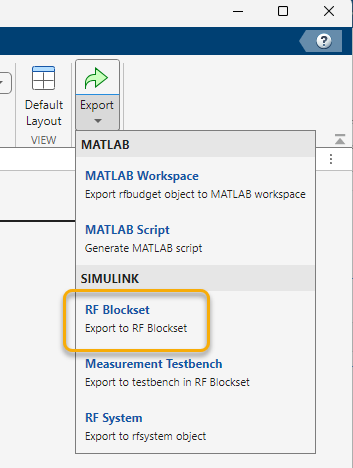

Open the available testbench `Exercise1_RFReceiverWithInterferer.slx.` 

open_system('Exercise1_RFReceiverWithInterferer.slx')

In the testbench, open the subsystem "PLACEHOLDER RF Receiver". 

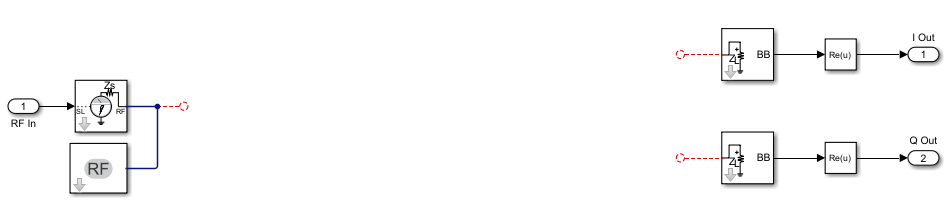

Copy the generated model from the RF Budget Analyzer app into the empty model. 

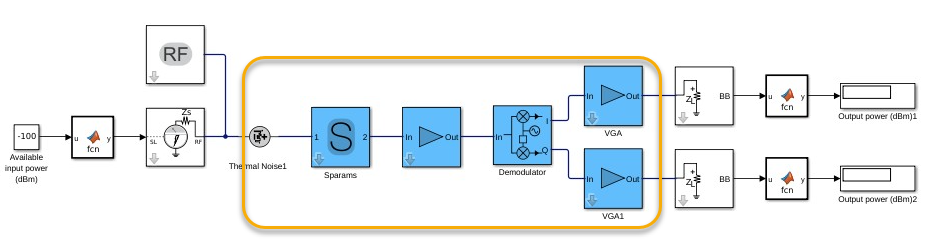

Spend a few minutes to familiarize yourself with testbench. In particular, inspect the baseband signal generation, the ADC, and the baseband receiver. 

*Why is the demodulator implemented with a quadrature (IQ) architecture?*

Suggestion: from the RF Budget Analyzer app, change the input frequency to 2.5GHz and generate a new RF Blockset model.

**2.2 **Open the mask of the **IQ demodulator block** (double click on the block), navigate to the Impairments tab and add the following impairments:

- LO to RF isolation = 105dB

- Phase noise frequency offset = [0.2,1,2,3,7]*1e6 Hz

- Phase noise levels  = [-70,-80,-95,-110,-120] dBc/Hz

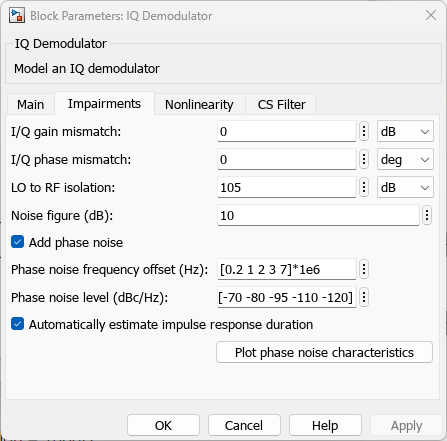

Run the model. Inspect the Chip Error Rate to be around 7%.

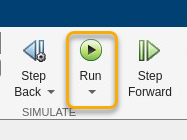

**2.3** Open the **RF input port** (Inport), and inspect its parameters.

*How many incoming signals are entering the receiver?*

Suggestion: in the MATLAB workspace verify what is the value of the variable `carrierFreqs`. As the variable is a vector, how many elements does it have?

Suggestion: click on the help button of the input port block. To learn more about how to use this block and the outport block, read the section "algorithms".

**2.4** Inspect the **spectrum of the receiver output signal** and verify the ChER in the following scenarios:

- Interfering signal power = -30dBm with DC offset correction (image on the left below)

- Interfering signal power = -200dBm, without DC offset correction (image on the right below)

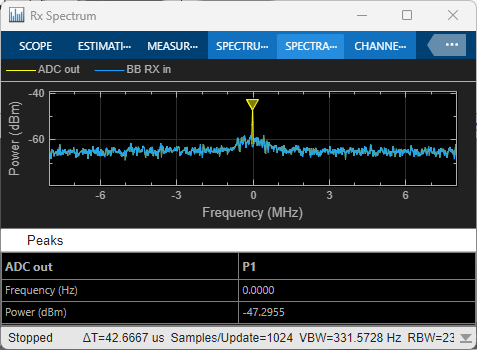 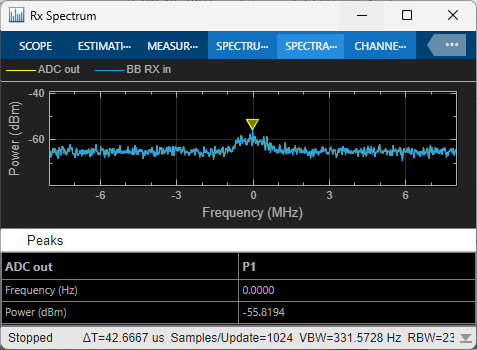

*What is the cause of the residual DC offset?*

Suggestion: to enable and disable the DC offset correction toggle the manual switch labeled "SW".

**Solution **

Execute the command below to visualize the RF receiver chain in the **RF Budget Analyzer** app.

rfBudgetAnalyzer('rfbudget_RFReceiver.mat') 

Open the model where the RF receiver has been integrated:

open_system('Solution1_RFReceiverWithInterferer.slx');

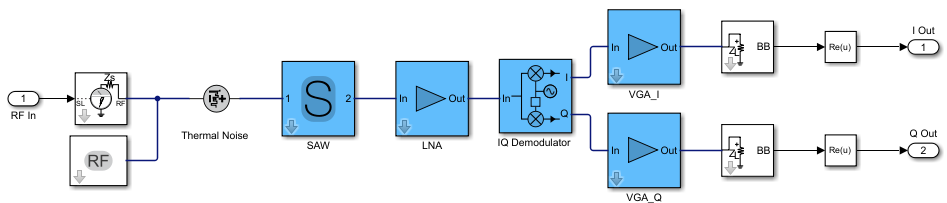

As the receiver implements a direct conversion architecture (the LO frequency is the same as the input frequency), a quadrature demodulator is required to recover the complex modulated signal.

Two signals are entering the receiver: the desired signal centered at 2.45GHz, and a high power interfering signal at 2.5GHz.

The interfering signal is exciting the non-linearity of the demodulator specified by means of IP2. In absence of a high-power signal, the residual DC offset is caused by finite LO to RF isolation. 

Extra: use the RF budget analysis of the chain to inspect the S-parameters of the cascade, and verify the phase angle of the last stage. Open the baseband receiver model, and see how this angle has been used to align the received constellation.

**Exercise outcome and summary**

In this exercise, you learned how to generate a model for system-level integration. You practiced multi-carrier simulation with interfering signals. You used analysis and simulation to cross-verify results and gain confidence in your design.